# Tests for debugging purposes

## The equations

## 
$$g(X,Q) = \sum_j \|X-Y_jQ_j\|^2 
\\
\nabla g(X,Q) = 2\bigg(\sum_j(X-Y_jQ_j), Y^\top(YQ-X)\bigg)
\\
\nabla^2 g(X,Q)[U,V] = \nabla g(U,V)$$


## Nonconvex problem

### Data and problem

n=3; % data dimension
k=5; % number of matrices
p=n; % size of factorization X of barycenter B
r=n; % size of factorization Y of data A (r>=p)
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

### Gradient

The slope should be 2. It appears to be: 1.99999.
If it is far from 2, then directional derivatives might be erroneous.


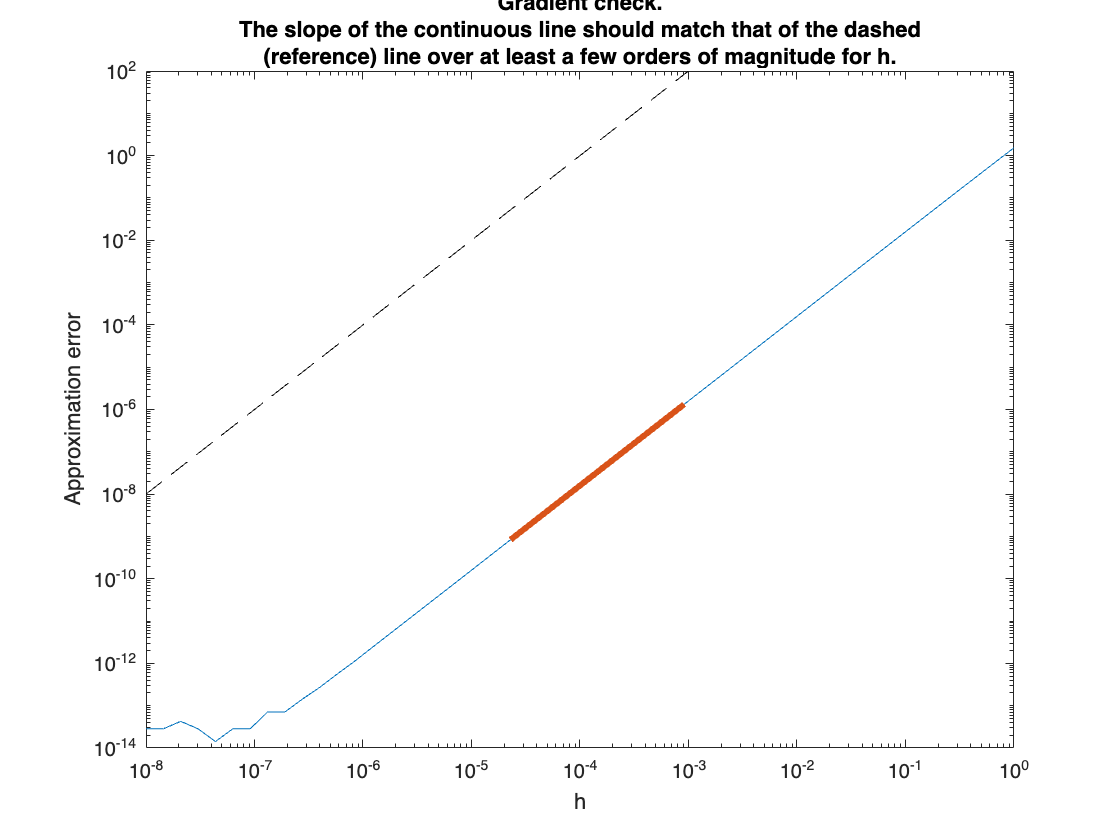

The residual should be 0, or very close. Residual: 1.62765e-14.
If it is far from 0, then the gradient is not in the tangent space.
In certain cases (e.g., hyperbolicfactory), the tangency test is inconclusive.


checkgradient(prob);

### Hessian

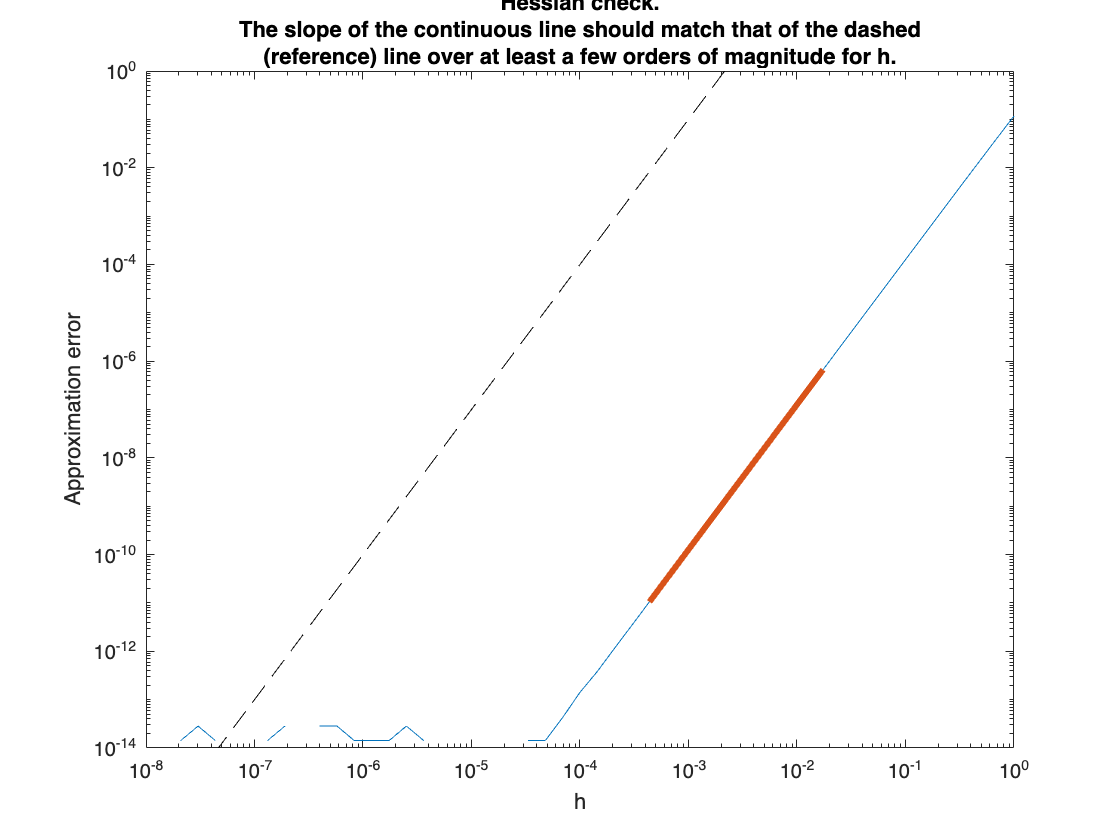

The slope should be 3. It appears to be: 2.99972.
If it is far from 3, then directional derivatives,
the gradient or the Hessian might be erroneous.
Tangency residual should be zero, or very close; residual: 1.36408e-15.
If it is far from 0, then the Hessian is not in the tangent space.
||a*H[d1] + b*H[d2] - H[a*d1+b*d2]|| should be zero, or very close.
	Value: 1.79193e-15 (norm of H[a*d1+b*d2]: 8.38618)
If it is far from 0, then the Hessian is not linear.
<d1, H[d2]> - <H[d1], d2> should be zero, or very close.
	Value: -1.24557 - -1.24557 = 6.66134e-16.
If it is far from 0, then the Hessian is not symmetric.


checkhessian(prob);

### Optimization

options.debug=1;
%options.statsfun = @variance_statsfun;
[x, xcost, info, options] = trustregions(prob,[],options);
figure;
semilogy([info.iter], [info.gradnorm], '.-',[info.iter],[info.cost],'.-');
xlabel('Iteration number');

## Convex problem

### Data and problem

n=4; % data dimension
k=3; % number of matrices
r=n; % size of factorization Y of data A (r>=p)
A = data(n,k,r);
prob2 = convex_problem(A);

### Gradient

checkgradient(prob2);

### Optimization

options.debug=1;
%options.statsfun = @variance_statsfun;
[x, xcost, info, options] = trustregions(prob2,[],options);
figure;
semilogy([info.iter], [info.gradnorm], '.-',[info.iter],[info.cost],'.-');
xlabel('Iteration number');